clc
clear

load("BaseDefinitions.mat")

Vout = zeros(15,96);
itrOut = zeros(15,1);
tic
% initialize voltage
for k=1:length(Psch)
    tolerance=1; 
    iteration = 0;
    V = complex(ones(nrBus,1),zeros(nrBus,1));
    Vprev = V;
    while (tolerance > 1e-3)
       
    % calculate voltage for pq buses
        for i = 2:nrBus
            % minus after the sum in eq to remove elements with j = i
            YV = (sum(Y(i,:).*V.') - Y(i,i)*V(i));
            V(i) = (1/Y(i,i)) * ((Psch(i,k)-j*Qsch(i,k)) / conj(V(i)) - YV);
        end
    
%         Adding acceleration
        V = Vprev + 1.7*(V-Vprev);

        Pitr = real(conj(V).*(Y*V));
        Qitr = -imag(conj(V).*(Y*V));

        iteration=iteration+1; % Increment iteration count
%         tolerance = max(abs(abs(V) - abs(Vprev))); % Tolerance
        %at the current iteration
        mismatchActive = max(abs(Psch(2:end,k) - Pitr(2:end)));
        mismatchReactive = max(abs(Qsch(2:end,k) - Qitr(2:end)));
        tolerance = max(mismatchActive, mismatchReactive); % Tolerance at the current iteration
        Vprev=V;
    end
    Vout(:,k) = V;
    itrOut(k) = iteration;
end
toc

Elapsed time is 1.335335 seconds.


meanItr = mean(itrOut)

meanItr = 199.1667

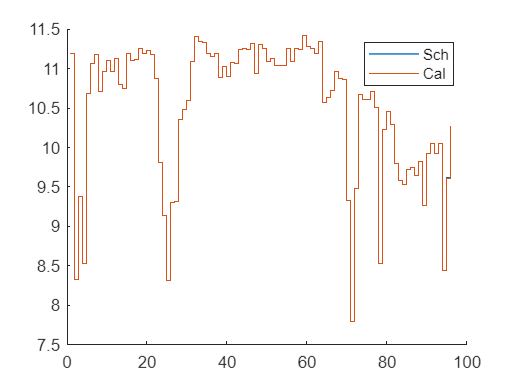


Pcal = real(conj(Vout).*(Y*Vout));
Qcal = -imag(conj(Vout).*(Y*Vout));
Vout;

figure
hold on
stairs(Psch(2,:))
stairs(Pcal(2,:))
legend("Sch", "Cal")
hold off

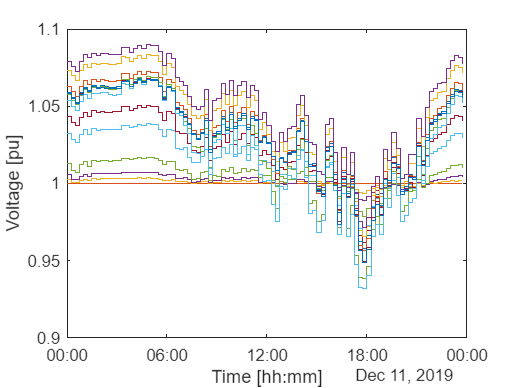


stairs(timestamp,abs(Vout).')
ylabel("Voltage [pu]")
xlabel("Time [hh:mm]")
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Gauss-Seidel-V','epsc')